Ripley dataset

load diabetes.mat

Xtrain = trainset;
Ytrain = labels_train;

Xtest = testset;
Ytest = labels_test;

Visualize the data. Inspect the data structure: what seems to be important prop-

erties of the data?

8 inputs , binary classification 

 Which classi�cation model do you think you need, based on the

complexity of the data?

linear, RBF 

## Visualize the training data

rng default % for reproducibility
Y = tsne(Xtrain,'Algorithm','barneshut','NumPCAComponents',4);

Error using pca
Too many input arguments.

Error in tsne (line 314)
    [~,X] = pca(X,'Centered',false,'Economy',false,'NumComponents',numPCA);


figure 
gscatter(Y(:,1),Y(:,2),Ytrain)


## Visualize the test data

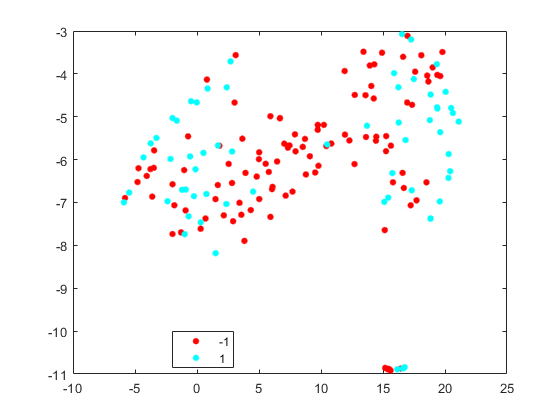

rng default % for reproducibility
Y = tsne(Xtest,'Algorithm','barneshut','NumPCAComponents',4);

figure 
gscatter(Y(:,1),Y(:,2),Ytest)

## Linear model

Try out different models (linear, polynomial, RBF kernel) with tuned hyperparameter

and kernel parameters. Compute the ROC curves. Which model performs best?

Which model would you choose?

Define the model parameters

type = 'c';
kernel_type = 'lin_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

gam = tunelssvm(model,'simplex','leaveoneoutlssvm', {'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.3491
                                          F(X)=         0.24667
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  leaveoneoutlssvm
    kernel function                 lin_kernel
 

 3. starting value:                   2.3491

 Iteration   Func-count    min f(x)    log(gamma)      Procedure

     1           2     2.466667e-01     2.0540           initial 
     2           4     2.466667e-01     2.0540           contract inside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=7.799383  , F(X)=2.466667e-01 

Obtained hyper-parameters: [gamma]: 7.7994


Compute the ROC curves

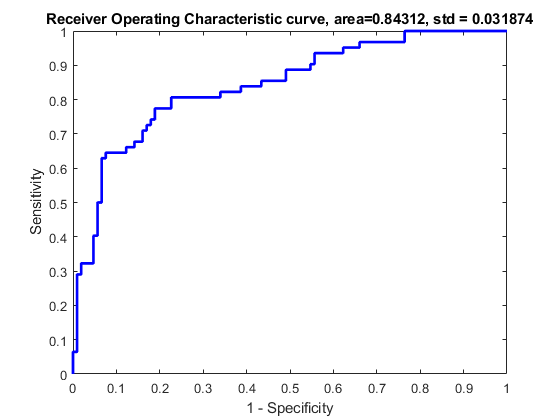

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'},{alpha, b},Xtest);
figure Name 'ROC Linear Kernel'
roc(Ylatent, Ytest);

## Polynomial model

Define the model parameters

type = 'c';
kernel_type = 'poly_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial hyperparameters for simplex...
  |-                                              -|
  **************************************************

 1. Simulated Annealing results:          [gam]         0.03832
                                          [t]           2.585
                                          [degree]      3
                                          F(X)=         0.37
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 poly_kernel
 

 3. starting values:                   0.03832       2.585           3

 Iteration   Func-count    min f(x)    log(gamma)      log(t)        Procedure

     1           3     3.666667e-01     -3.2618         2.1497         initial   
     2           5     3.100000e-01     -5.6618         2.7497         expand   
     3           6     3.100000e-01     -5.6618         2.7497         reflect   
     4     

Compute the ROC curves

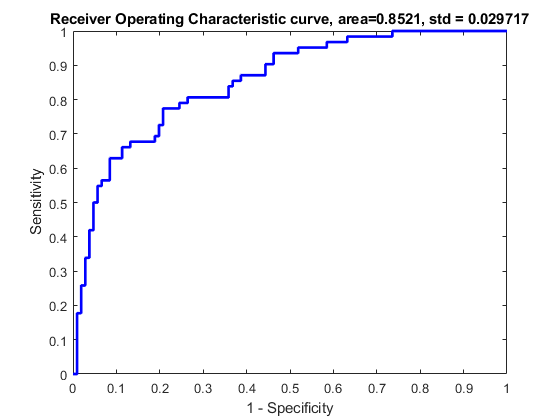

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);

## RBF model

Define the model parameters

type = 'c';
kernel_type = 'RBF_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.9144
                                          [sig2]        18.709
                                          F(X)=         0.24667
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   3.91437       18.709

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     2.466667e-01     1.3647        2.9290      initial 
     2           5     2.466667e-01     1.3647        2.9290      contract outside 
     3           6     2.466667e-01     1.3647        2.9290      reflect 
     4          10     2.466667e-01     1.3647        2.9290   

Compute the ROC curves

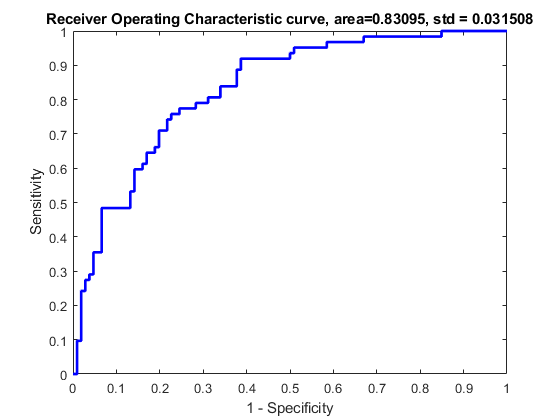

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);